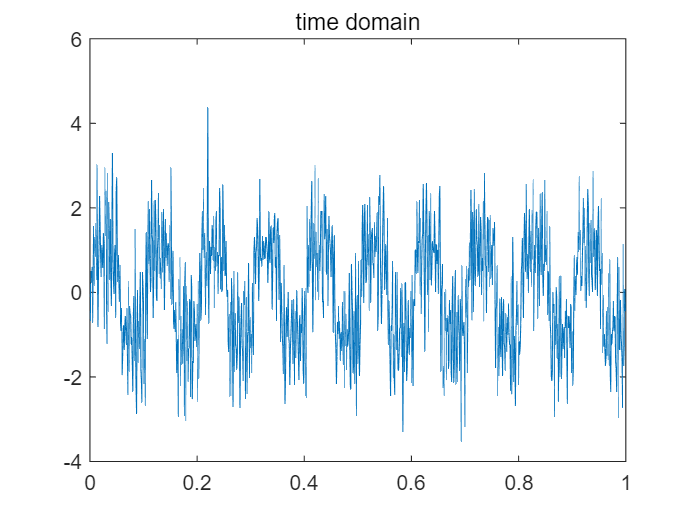

%(1)load file
load('Q1\Q1.mat');

%(2)load the measurement and plot it in the time domain
t1=0:1/Fs:1;
t1=t1(1:end-1);
plot(t1,xs_noised);title("time domain");

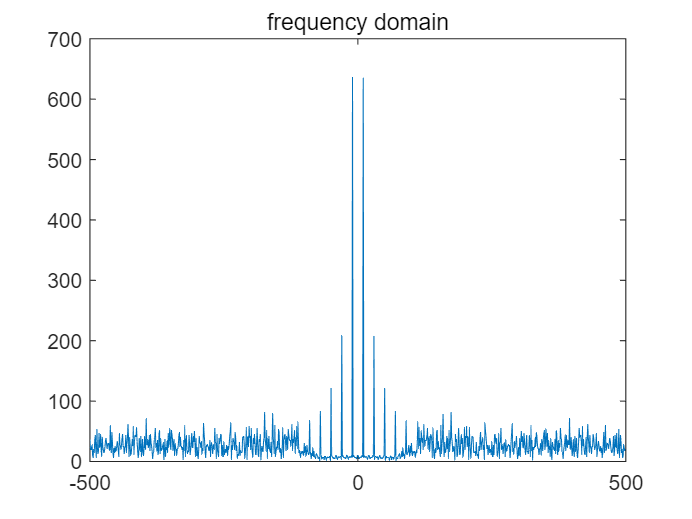


%(3)
Y=fft(xs_noised);
N=1000;
f=(0:N-1)*Fs./(N);
fY=fftshift(Y);
t2=(-500:499);
plot(t2,abs(fY));%plot the amplitude spectrum of the measurement in the frequency domain

title("frequency domain");


%disp(abs(Y));%(3) disp Y to find the frequency
%if the documents are shown,it will take too many pages
%so add "%" to let the output of the code easier to look

disp("the frequency bound of lowpass signal is about 90~100 so let the lowpass be 95");

the frequency bound of lowpass signal is about 90~100 so let the lowpass be 95


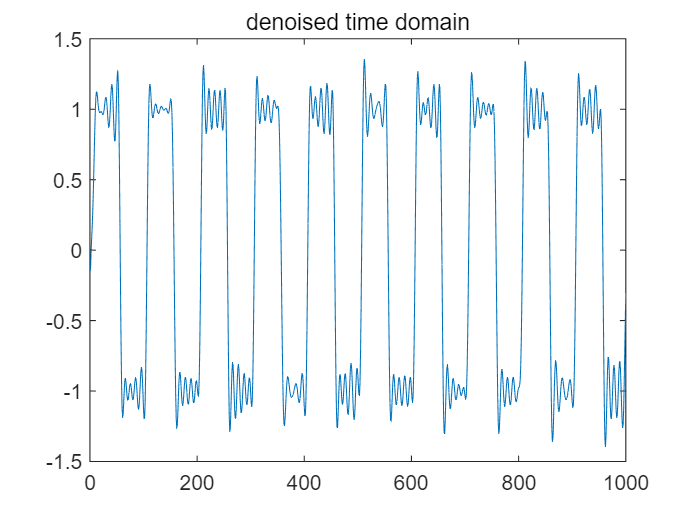

%use disp command to give an estimated frequency bound of the desired lowpass signal.

%(4)
for i=[95:905]
    Y(i)=0;
end

x=ifft(Y);%denoise the measurement using FFT through fft command
plot(real(x));%plot the waveform of the denoised signal in time domain
title("denoised time domain");

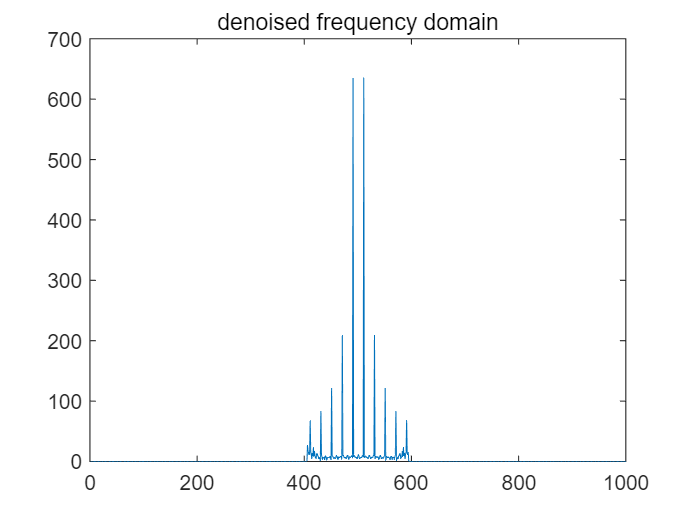

plot(abs(fftshift(Y)));%plot the waveform of the denoised signal in frequency domain
title("denoised frequency domain");

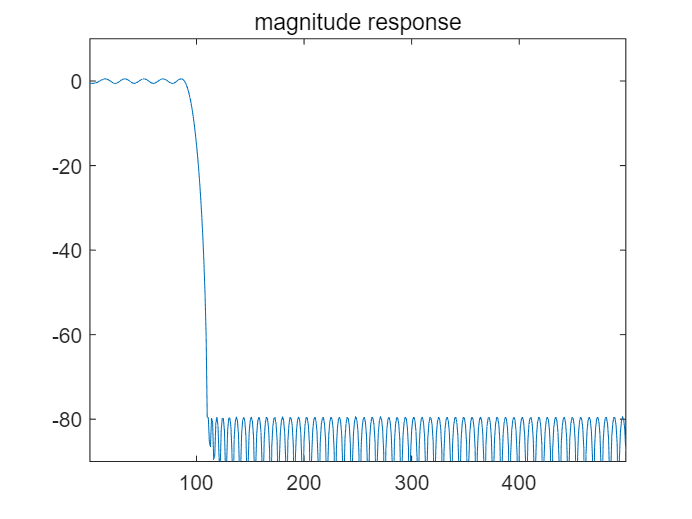


%(5)design an FIR filter use fdatool command and filter the signal with filter command
%disp(Num);
[hang,l]=size(Num);
ans=zeros(1,1000);
for i=[1:1000]
    for j=[1:l]
        ans(i)=ans(i)+Num(j)*(exp(2*pi*i*(1i)/1000))^(j-1);
    end
end
ans=ans(1:499);
plot(20*log10(abs(ans)));%(1)plot the magnitude response of the filter in frequency domain
axis([1 499 -90 10]);title("magnitude response");

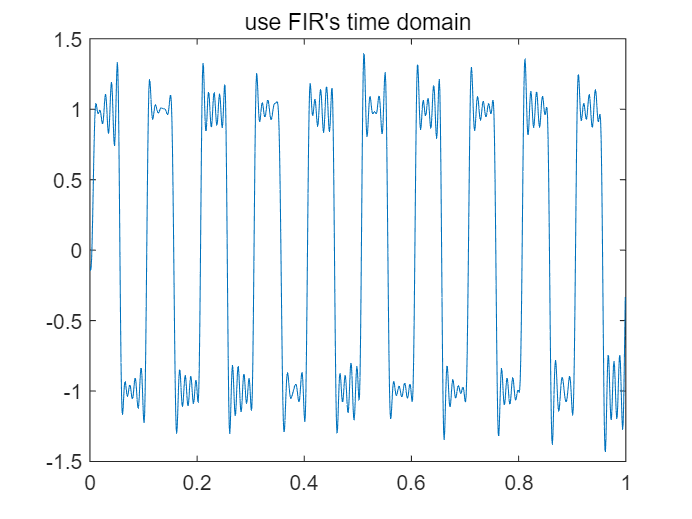


%explaination:
%when set the parameters of the fdatool(filterDesigner) ,let the Fs=1000
%because the max frequency is 1000
%set the Fpass=90 because from the graph of the xs_noise signal
%in frequenct domain, we can see that the lowpass signal is 90~100 fs
%and set the Fstop be 110, to have a suitable filtering range

xs_noised=[xs_noised,zeros(1,64)];
f=filter(my_filter1,xs_noised);
f=f(64:1063);
plot(t1,f);%(2)plot the filtered signal in time domain
title("use FIR's time domain");

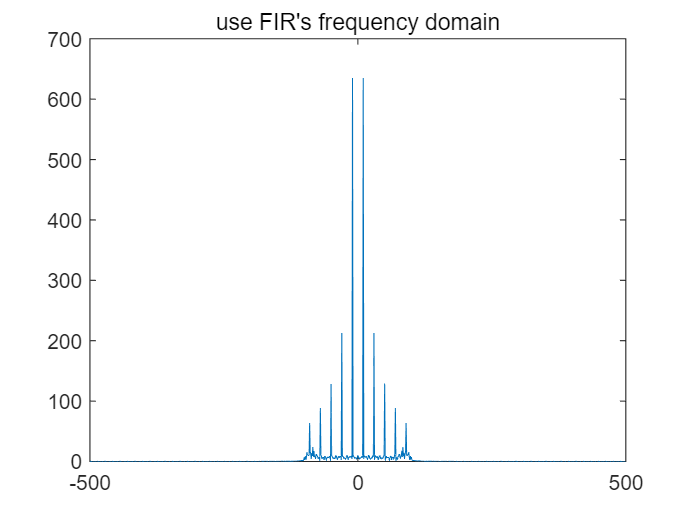

plot(t2,abs(fftshift(fft(f))));%(3)plot the amplitude spectrum of the filtered signal in frequency domain
title("use FIR's frequency domain");